# Tarea: Implementación de funciones de activación.

#### **Juan Uriel Legaria Peña**

#### **Asignatura: Inteligencia Artificial**

#### **06/10/2020**

En este reporte se tratará en forma breve la forma en que se implementaron las funciones de activación revisadas en clase. La idea será utilizar dichas funciones como bloques, que ayudarán a construir las distiintas redes neuronales que se verán en las próximas sesiones. 

Como se nos había mencionado, la mayor parte de estas funciones de transferencia toma como entrada la salida de una neurona, que arbitrariamente podriamos denotar como $$x$$. La excepción a esto sería la función competitiva, el cual toma un arreglo saliente de diversas neuronas $\bf{x}$ y asigna un valor de 1 al mayor de ellos y 0 a los demás. 

## La clase ActivationFunction

Con la intención de explotar está característica común de la mayoría de las funciones respecto a la entrada, se definió una clase padre denominada ActivationFunction la cual contiene dos métodos importantes, un método abstracto compute(x), a instanciar en las clases que hereden de ella, y un método plotActivationFunction() la cual arroja un gráfico de la función de activación. Esto simplemente con el propósito de tener información visual de la misma. 

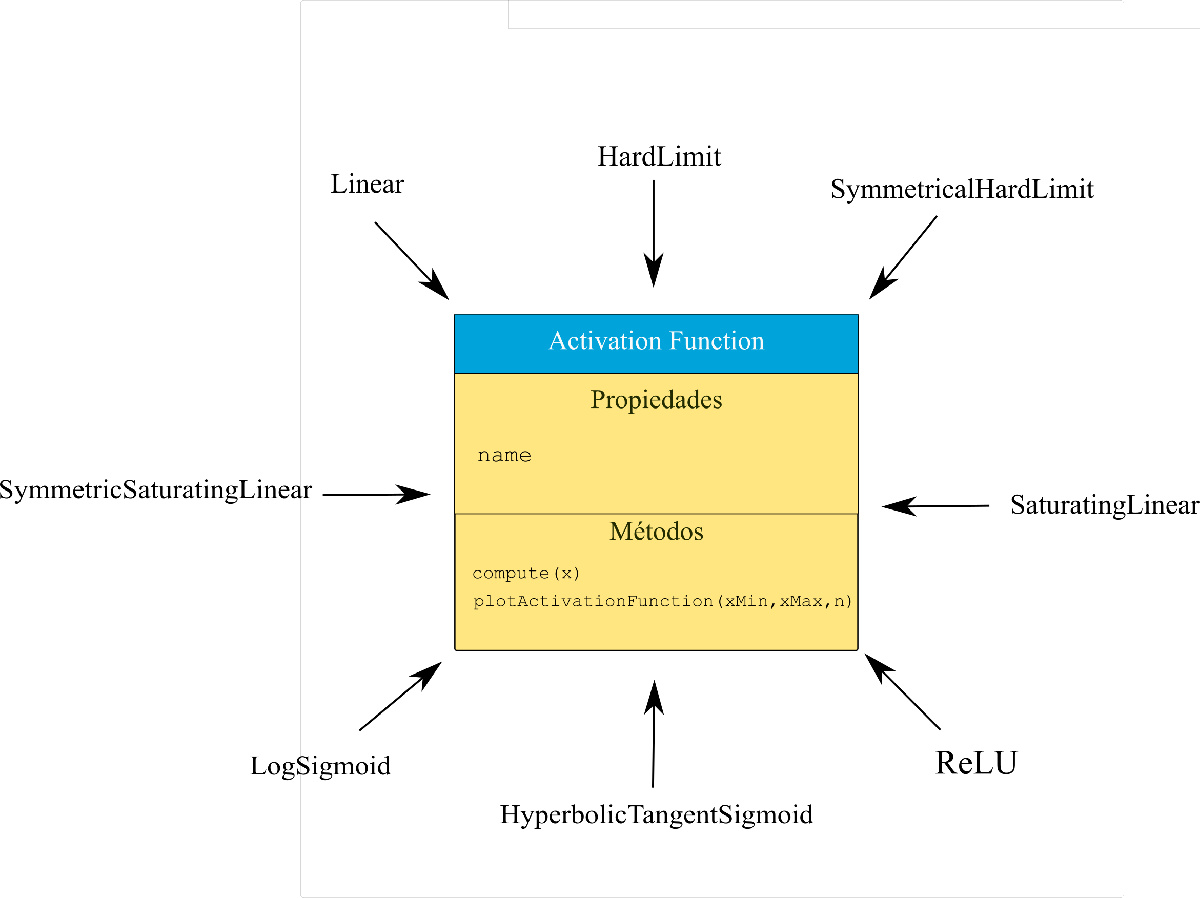

**Figura 1.- Las funciones de activación heredan de la clase ActivationFunction**

Continuaremos con una descripción bastante sistemática de las diferentes funciones implementadas. 

## Hard Limit

HardLimit toma un valor de uno cuando la entrada es mayor o igual a cero y un valor de cero en el caso contrario. Esta es una de las funciones que tiene una naturaleza binaria, i.e. que dependiendo de la entrada da como output dos valores posibles. Este mecanismo de thresholding es análogo al que se tiene para las neuronas, donde unicamente si el potencial generado por la entrada de iones supera cierto umbral se dispara un potencial de acción. Para el caso de HardLimit el umbral viene dado en el valor cero pero es posible moverlo ajustando el valor de bias.

Su gráfico se ve de la siguiente forma 

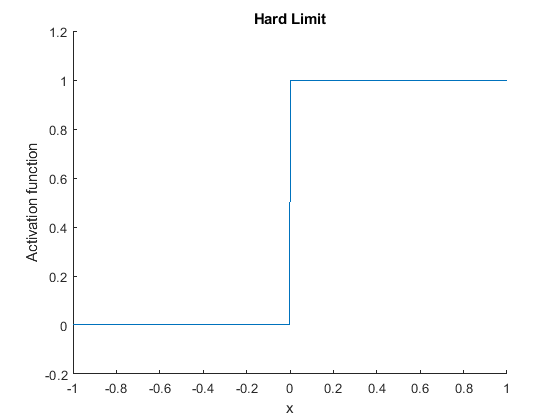

%Store the activation function
h = HardLimit();
%Plot it
h.plotActivationFunction(-1,1,1000);

## **Symmetrical Hard Limit**

Esta función es bastante similar a la que se describió anteriormente sin embargo ahora la salida adoptará un valor de  1 o de -1 dependiendo de si $x\geq0$ o $x<0$ respectivamente. La función es en realidad antisimétrica, ya que $f(x)  = -f(-x)$.

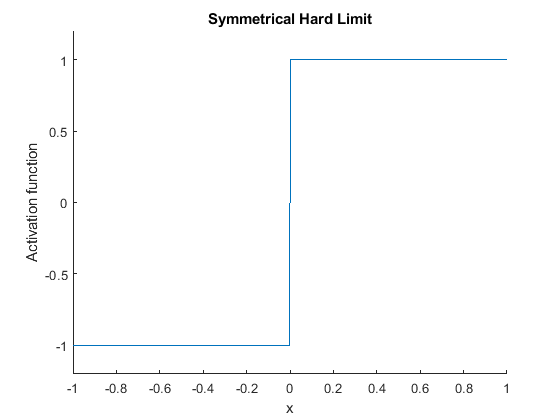

%Store the activation function
h = SymmetricalHardLimit();
%Plot it
h.plotActivationFunction(-1,1,1000);

### Linear 

Esta función devuelve sencillamente la misma entrada inalterada que se le proporcione. Generalmente se utiliza cuando se desea pasar la información obtenida en forma fiel hacia algún nuevo modulo de la red neuronal, como ocurre por ejemplo en la red Hamming. Los nodos que usan esta función de transferencia guardan cierta analogía con lo que serian las interneuronas en el sistema nervioso central.

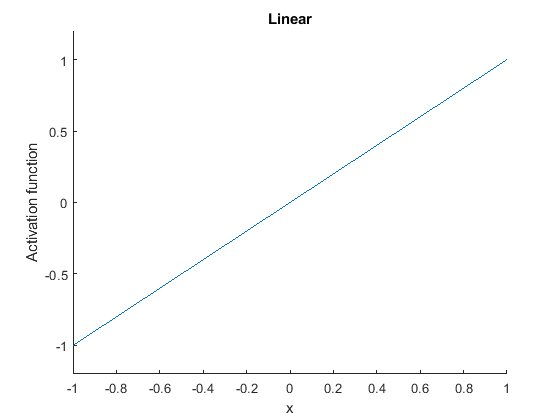

%Store the activation function
h = Linear();
%Plot it
h.plotActivationFunction(-1,1,1000);

### Saturating Linear

La función de activación de saturación lineal se define igual que la función lineal en un intervalo cerrado de cero a uno  sin embargo para valores mayores a uno o menores que 0 ejerce un efecto de clipping, quizás aquí si sea mas conveniente dar como tal una descripción simbólica de la función, esta tiene la siguiente forma:


$$f(x) = 
     \begin{cases}
       0&\quad x < 0\\
       x&\quad 0 \leq x \leq 1\\
1&\quad x>1

     \end{cases}$$


Lo que se logra mediante el efecto de clipping es una restricción del rango posible de valores de salida. Esto me imagino pudiese ayudar a que ciertos pesos grandes no dominen por completo las vias que toma la red. 

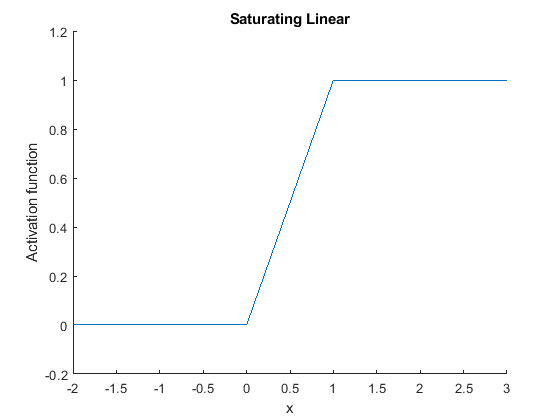

%Store the activation function
h = SaturatingLinear();
%Plot it
h.plotActivationFunction(-2,3,1000);

### **Symmetric Saturating Linear**

Es muy similar a la functión lineal de saturación sin embargo presenta antisimetría (parecido a lo que ocurría en el caso de Symmetrical Hard Limit). Esta se define de la siguiente manera:


$$f(x) = 
     \begin{cases}
       -1&\quad x < -1\\
       x&\quad -1 \leq x \leq 1\\
1&\quad x>1

     \end{cases}$$


Su respectivo gráfico es el siguiente:

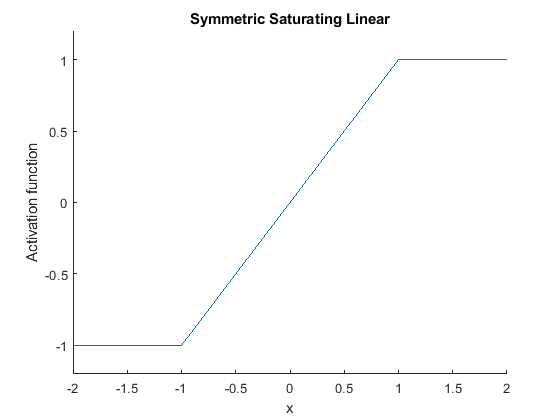

%Store the activation function
h = SymmetricSaturatingLinear();
%Plot it
h.plotActivationFunction(-2,2,1000);

### **Log-Sigmoid**

Log-Sigmoid es una función de activación que actua en una forma un tanto similar a las dos anteriores con la ventaja adicional de que su derivada esta definida para todas las entradas, si observamos el gráfico de la función de saturación lineal simétrica, se hace evidente que la derivada no existe ni para -1 ni para 1, aquí si me permiten algo de formalismo matemático, una de las proposiciones que se aprenden en cálculo es: $\text{Si la derivada existe en el punto } c \in \mathbb{R}  \to \lim_{x\to c^{+}} f'(x) = \lim_{x\to c^{-}} f'(x) = f'(x)$. La proposición contrapositiva de esto indica que si el límite de la derivada por la derecha y por la izquierda en un punto son distintas, la derivada no existe en dicho punto. Así por ejemplo, para el punto -1 del gráfico anterior se observa que al acercarse por la derecha la pendiente pareciera ser igual a uno, mientras que al hacerlo por la izquierda pareciera tener un valor de 0, ergo la derivada no puede estar definida en dicho punto. 

La cuestión de la diferenciabilidad de la función de transferencia cobra relevancia al querer ver como cambian los pesos de las neuronas respecto a errores en los valores obtenidos por la red (Esto para saber que pesos modificar en el entrenamiento para tener mas influencia en el resultado), matemáticamente esto basicamente se hace mediante una cadena de multiplicaciones de derivadas de las pesos y de las funciones de activación, es por tanto necesario que dichas funciones sean derivables y es ahí donde se suelen utilizar Log-sigmoid, que seria como una versión continua de Hard Limit, y Hyperbolic Tangent Sigmoid, que sería análoga a Symmetric Hard Limit. . 

La ecuación de Log Sigmoid es:


$$f(x) = \frac{1}{1+\exp(-x)}$$


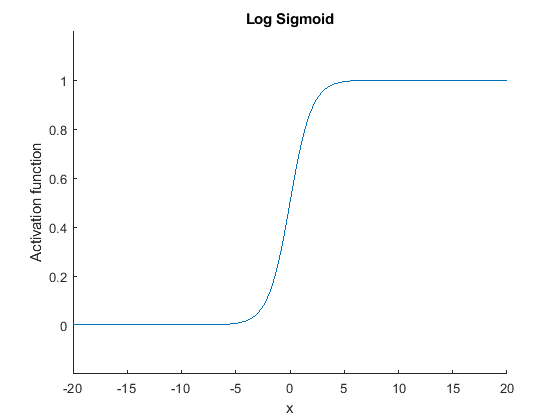

%Store the activation function
h = LogSigmoid();
%Plot it
h.plotActivationFunction(-20,20,1000);

### **Hyperbolic Tangent Sigmoid**

Hyperbolic Tangent Sigmoid sería una especie de versión continua de Symmetric Hard Limit, basicamente esta funciión es el cociente entre el coseno y seno hiperbólicos:


$$f(x) = \frac{\cosh{x}}{\sinh{x}} = \frac{(\exp{(x)} +\exp{(-x))/2}}{(\exp{(x)} -\exp{(-x))/2}} =\frac{\exp{(x)} +\exp{(-x)}}{\exp{(x)} -\exp{(-x)} $$


y su gráfico se ve de la siguiente forma:

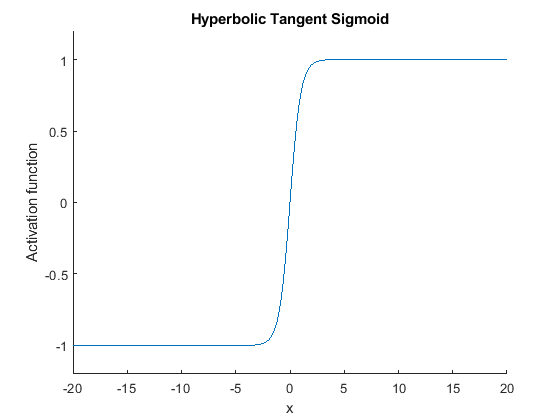

%Store the activation function
h = HyperbolicTangentSigmoid();
%Plot it
h.plotActivationFunction(-20,20,1000);

### **ReLU**

ReLU es una de las funciones de activación mas importantes para redes neurológicas profundas. La función en sí es bastante sencilla y se resume en la siguiente expresión:


$$f(x) = 
     \begin{cases}
       0&\quad x < 0\\
       x&\quad x\geq 0\\
     \end{cases}$$


Esta tiene dos características esenciales, la primera es que se trata de una función no lineal, y por consiguiente amplía mucho el espectro de comportamiento que podemos conseguir con la red neuronal en cuestión. La siguiente virtud de la función es que como solo se tiene un solo valor de thresholding se elimina uno de los fenómenos mas problemáticos que surgian en los métodos de backpropagation: el *desvanecimiento de los coeficientes*. Este problema surge cuando al realizar la cadena de multiplicaciones de derivadas de la cual se habló en la sección anterior se obtienen valores de gradiente muy pequeños, lo cual resulta en un entrenamiento muy lento de la red. Esto se contrarresta un poco al permitir valores positivos de salida arbitrariamente grandes usando ReLU.

### **Competitive**

Finalmente se tiene la función competitiva, esta basicamente recibe como entrada un arreglo de salidas de varias neuronas y lo que hace es mandar el output máximo a 1 y todos los demás a 0, así si por ejemplo el arreglo de salidas es (1,2,3), la función competitiva lo transformara a (0,0,1).

output = [1;2;3];
h = Competitive();
disp(output);

     1
     2
     3




disp(h.compute(output));

     0
     0
     1

